%% PARTE 2 · (a)+(b)  — WAV -> MP3 a dos bitrates y tiempo de proceso
clear; clc;

% --- Configuración principal ---
wavFile = 'P4audioSTM.wav';                     % tu WAV
assert(isfile(wavFile), 'No se encuentra: %s', wavFile);
bitrates = [320 128];                           % kbps
outDir   = fullfile(pwd,'mp3_out'); if ~exist(outDir,'dir'), mkdir(outDir); end

% (OPCIONAL) Si ya tienes la ruta al ejecutable, descomenta UNA de estas:
% encoderPath = "C:\ffmpeg\bin\ffmpeg.exe";     % Windows ejemplo
% encoderPath = "/usr/local/bin/ffmpeg";        % macOS/Linux ejemplo
encoderPath = "";                               % por defecto vacío

% --- Detección de encoder (ffmpeg o lame) ---
[encCmd, encType] = pickEncoder(encoderPath);

C:\Users\andre\AppData\Local\Microsoft\WinGet\Packages\Gyan.FFmpeg_Microsoft.Winget.Source_8wekyb3d8bbwe\ffmpeg-8.0-full_build\bin\ffmpeg.exe 


fprintf('Encoder seleccionado: %s (%s)\n', encCmd, encType);

Encoder seleccionado: ffmpeg (ffmpeg)



% --- Info del WAV (solo informativa) ---
info = audioinfo(wavFile);
fprintf('Entrada: %s | Fs=%d Hz | Canales=%d | Duración=%.2fs\n', ...
    wavFile, info.SampleRate, info.NumChannels, info.Duration);

Entrada: P4audioSTM.wav | Fs=44100 Hz | Canales=2 | Duración=19.97s



% --- Codificación y cronometraje ---
results = struct('kbps',[],'mp3File',[],'elapsed_s',[]);
for k = 1:numel(bitrates)
    br = bitrates(k);
    mp3File = fullfile(outDir, sprintf('P2_%dkbps.mp3', br));
    if isfile(mp3File), delete(mp3File); end
    switch encType
        case 'ffmpeg'
            cmd = sprintf('"%s" -y -hide_banner -loglevel error -i "%s" -vn -b:a %dk "%s"', ...
                           encCmd, wavFile, br, mp3File);
        case 'lame'
            cmd = sprintf('"%s" --quiet --preset cbr %d "%s" "%s"', ...
                           encCmd, br, wavFile, mp3File);
        otherwise
            error('No hay encoder disponible.');
    end
    fprintf('Codificando a %3d kbps -> %s\n', br, mp3File);
    t0 = tic; status = system(cmd); elapsed = toc(t0);
    if status~=0 || ~isfile(mp3File)
        error('Fallo codificando a %d kbps. Revisa el encoder y la ruta.', br);
    end
    results(k).kbps = br; results(k).mp3File = mp3File; results(k).elapsed_s = elapsed;
    fprintf('  Tiempo: %.3f s | Tamaño: %.1f MB\n', elapsed, dir(mp3File).bytes/1024/1024);
end

Codificando a 320 kbps -> C:\Users\andre\Desktop\Universidad\ICAI\4\Stel\Practicas\PracticasSTM\PracticasSTM\P4\Matlab MPEG1_III\mp3_out\P2_320kbps.mp3


  Tiempo: 1.217 s | Tamaño: 0.8 MB


Codificando a 128 kbps -> C:\Users\andre\Desktop\Universidad\ICAI\4\Stel\Practicas\PracticasSTM\PracticasSTM\P4\Matlab MPEG1_III\mp3_out\P2_128kbps.mp3


  Tiempo: 0.381 s | Tamaño: 0.3 MB



fprintf('\n--- Parte 2 (a)+(b): Resumen ---\n');


--- Parte 2 (a)+(b): Resumen ---


for k=1:numel(results)
    s = dir(results(k).mp3File);
    fprintf('  %3d kbps | tiempo = %.3f s | tamaño = %.1f MB | %s\n', ...
        results(k).kbps, results(k).elapsed_s, s.bytes/1024/1024, results(k).mp3File);
end

  320 kbps | tiempo = 1.217 s | tamaño = 0.8 MB | C:\Users\andre\Desktop\Universidad\ICAI\4\Stel\Practicas\PracticasSTM\PracticasSTM\P4\Matlab MPEG1_III\mp3_out\P2_320kbps.mp3
  128 kbps | tiempo = 0.381 s | tamaño = 0.3 MB | C:\Users\andre\Desktop\Universidad\ICAI\4\Stel\Practicas\PracticasSTM\PracticasSTM\P4\Matlab MPEG1_III\mp3_out\P2_128kbps.mp3



% ======= Funciones locales =======
function [encCmd, encType] = pickEncoder(userPath)
    encCmd = ''; encType = '';

    % 1) Ruta directa del usuario
    if strlength(userPath) > 0 && isfile(userPath)
        encCmd = char(userPath);
        if contains(lower(encCmd),'ffmpeg'), encType = 'ffmpeg'; else, encType = 'lame'; end
        return;
    end

    % 2) PATH del sistema
    if ispc
        if system('where ffmpeg') == 0, encCmd = 'ffmpeg'; encType = 'ffmpeg'; return; end
        if system('where lame')   == 0, encCmd = 'lame';   encType = 'lame';   return; end
    else
        if system('command -v ffmpeg') == 0, encCmd = 'ffmpeg'; encType = 'ffmpeg'; return; end
        if system('command -v lame')   == 0, encCmd = 'lame';   encType = 'lame';   return; end
    end

    % 3) Carpetas locales típicas (usar CELL ARRAY)
    cand = {
        fullfile(pwd,'ffmpeg','bin','ffmpeg.exe')
        fullfile(pwd,'ffmpeg','bin','ffmpeg')
        fullfile(pwd,'tools','ffmpeg','bin','ffmpeg.exe')
        fullfile(pwd,'tools','ffmpeg','bin','ffmpeg')
        fullfile(pwd,'lame','lame.exe')
        fullfile(pwd,'lame','lame')
    };

    for i = 1:numel(cand)
        if isfile(cand{i})
            encCmd = cand{i};
            if contains(lower(encCmd),'ffmpeg'), encType = 'ffmpeg'; else, encType = 'lame'; end
            return;
        end
    end

    error(['No se encontró un encoder MP3.\n' ...
           'Solución rápida:\n' ...
           '  • Descarga FFmpeg “portable” y coloca el ejecutable en ./ffmpeg/bin/\n' ...
           '  • O indica la ruta en encoderPath (p.ej. C:\\ffmpeg\\bin\\ffmpeg.exe)\n' ...
           '  • O añade FFmpeg/LAME al PATH del sistema y reinicia MATLAB.']);
end


%% PARTE 2 · (c) — Tamaños y ratios de compresión (WAV vs MP3)
% Requisitos: tener el WAV original y al menos dos MP3 en ./mp3_out
clc;

% --- Localiza el WAV de referencia ---
if ~exist('wavFile','var') || ~isfile(wavFile)
    wavFile = 'P4audioSTM.wav';   % ajusta si tu WAV se llama distinto
end
assert(isfile(wavFile), 'No se encuentra el WAV: %s', wavFile);
sW = dir(wavFile);  wavBytes = sW.bytes;

% --- Localiza los MP3 (desde 'results' o explorando carpeta) ---
mp3Dir = fullfile(pwd,'mp3_out');
assert(isfolder(mp3Dir), 'No existe la carpeta de salida: %s', mp3Dir);

mp3Files = string([]);
if exist('results','var') && ~isempty(results)
    mp3Files = string(arrayfun(@(r) r.mp3File, results, 'UniformOutput', false));
end
if isempty(mp3Files)
    d = dir(fullfile(mp3Dir,'*.mp3'));
    assert(~isempty(d), 'No se han encontrado MP3 en %s', mp3Dir);
    % Usa todos los MP3 que haya (se listarán con su tamaño)
    mp3Files = string(fullfile({d.folder},{d.name}));
end

% --- Prepara tabla de resultados ---
names  = ["WAV (origen)"];
sizesB = [wavBytes];
ratio  = [1.0];        % WAV/WAV
note   = ["—"];

for k = 1:numel(mp3Files)
    f = mp3Files(k);
    if ~isfile(f), warning('Saltando (no existe): %s', f); continue; end
    s = dir(f);
    names(end+1)  = "MP3: " + string(s.name);               %#ok<AGROW>
    sizesB(end+1) = s.bytes;                                %#ok<AGROW>
    ratio(end+1)  = wavBytes / s.bytes;                     %#ok<AGROW>
    note(end+1)   = sprintf('Reducción %.1f%%', 100*(1 - s.bytes/wavBytes)); %#ok<AGROW>
end

% --- Formatea y muestra ---
sizesMB = sizesB/1024/1024;
T = table(names.', sizesMB.', ratio.', note.', ...
          'VariableNames', {'Fichero','Tamano_MB','Ratio_WAV_div','Comentario'});

disp('--- Parte 2 (c): Tamaños y ratios de compresión ---');

--- Parte 2 (c): Tamaños y ratios de compresión ---


fprintf('WAV:   %s | %.2f MB\n', sW.name, sizesMB(1));

WAV:   P4audioSTM.wav | 5.04 MB


for i = 2:numel(sizesMB)
    fprintf('MP3:   %s | %.2f MB | Ratio = %.2f:1 | %s\n', ...
        names(i), sizesMB(i), ratio(i), note(i));
end

MP3:   MP3: P2_320kbps.mp3 | 0.76 MB | Ratio = 6.59:1 | Reducción 84.8%
MP3:   MP3: P2_128kbps.mp3 | 0.31 MB | Ratio = 16.48:1 | Reducción 93.9%


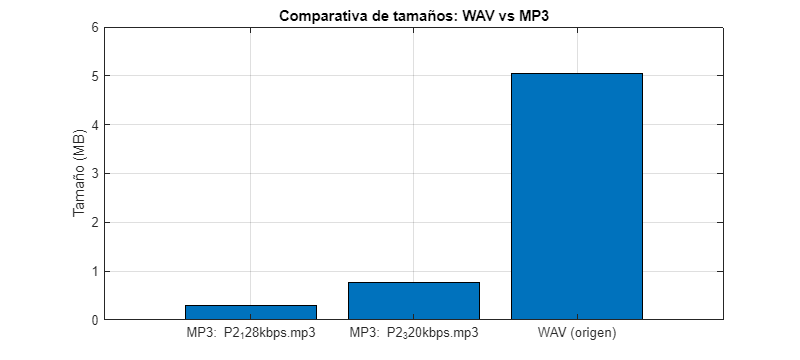


% --- (Opcional) gráfica rápida de tamaños ---
figure('Color','w','Position',[120 120 800 360]); 
bar(categorical(names), sizesMB);
ylabel('Tamaño (MB)'); title('Comparativa de tamaños: WAV vs MP3');
grid on;

%% PARTE 2 · (d) — Calidad: comparación visual, auditiva y métricas objetivas
% Requisitos: WAV original y al menos dos MP3 generados (Parte 2 a–c).
% Autocontenido: si no hay variables previas, busca ./mp3_out.

clearvars -except wavFile results; clc;

%% ---------- Localiza archivos ----------
if ~exist('wavFile','var') || ~isfile(wavFile)
    wavFile = 'P4audioSTM.wav';                          % ajusta si tu WAV se llama distinto
end
assert(isfile(wavFile), 'No se encuentra el WAV: %s', wavFile);

mp3Dir = fullfile(pwd,'mp3_out');
assert(isfolder(mp3Dir), 'Falta la carpeta ./mp3_out (ejecuta antes la Parte 2 a–c).');

if exist('results','var') && ~isempty(results)
    mp3Files = string(arrayfun(@(r) r.mp3File, results, 'UniformOutput', false));
else
    d = dir(fullfile(mp3Dir,'*.mp3'));
    assert(~isempty(d), 'No hay MP3 en ./mp3_out');
    mp3Files = string(fullfile({d.folder},{d.name}));
end
mp3Files = unique(mp3Files(:));

%% ---------- Lectura y preparación (mono, remuestreo si procede) ----------
[x,Fs] = audioread(wavFile); if size(x,2)>1, x = mean(x,2); end
Y = cell(numel(mp3Files),1);
for i=1:numel(mp3Files)
    [y,FsY] = audioread(mp3Files(i));
    if size(y,2)>1, y = mean(y,2); end
    if FsY~=Fs, y = resample(y, Fs, FsY); end
    Y{i} = y(:);
end

%% ---------- Alineación (correlación) + igualación de nivel ----------
xRef = x(:);
pairs = struct('name',{},'y_al',{},'lag',{},'gain',{},'x_cmp',{},'y_cmp',{});
for i=1:numel(Y)
    y = Y{i};
    [lag, y_al] = align_by_xcorr(xRef, y, Fs);       % y alineada a x
    % iguala ganancia RMS en la parte solapada
    N = min(numel(xRef), numel(y_al));
    xr = xRef(1:N); yr = y_al(1:N);
    g  = rms(xr)/max(rms(yr),eps);  yr = yr * g;

    pairs(i).name  = string(mp3Files(i));
    pairs(i).y_al  = yr;
    pairs(i).lag   = lag;
    pairs(i).gain  = g;
    pairs(i).x_cmp = xr;
    pairs(i).y_cmp = yr(1:numel(xr));
end

%% ---------- Métricas objetivas ----------
W = hamming(2048,'periodic'); hop = 512;
fprintf('\n--- Parte 2 (d) · Métricas ---\n');


--- Parte 2 (d) · Métricas ---


metricsTbl = table('Size',[0 6], 'VariableTypes', ...
    {'string','double','double','double','double','double'}, ...
    'VariableNames', {'Archivo','SNR_dB','SegSNR_dB','RMSE','LSD_dB','Lag_muestras'});

for i=1:numel(pairs)
    xr = pairs(i).x_cmp; yr = pairs(i).y_cmp; e = xr-yr;
    snr_db    = 20*log10(rms(xr)/max(rms(e),eps));
    segsnr_db = seg_snr(xr, yr, W, hop);
    rmse      = sqrt(mean(e.^2));
    lsd_db    = lsd_stft(xr, yr, W, hop);
    metricsTbl = [metricsTbl; {pairs(i).name, snr_db, segsnr_db, rmse, lsd_db, pairs(i).lag}]; %#ok<AGROW>
    fprintf('  %s\n    SNR=%.2f dB | SegSNR=%.2f dB | RMSE=%.4f | LSD=%.2f dB | lag=%d\n', ...
        strip_filename(pairs(i).name), snr_db, segsnr_db, rmse, lsd_db, pairs(i).lag);
end

  P2_128kbps.mp3
    SNR=38.60 dB | SegSNR=34.95 dB | RMSE=0.0006 | LSD=2.07 dB | lag=1729
  P2_320kbps.mp3
    SNR=39.57 dB | SegSNR=34.96 dB | RMSE=0.0005 | LSD=1.58 dB | lag=1729


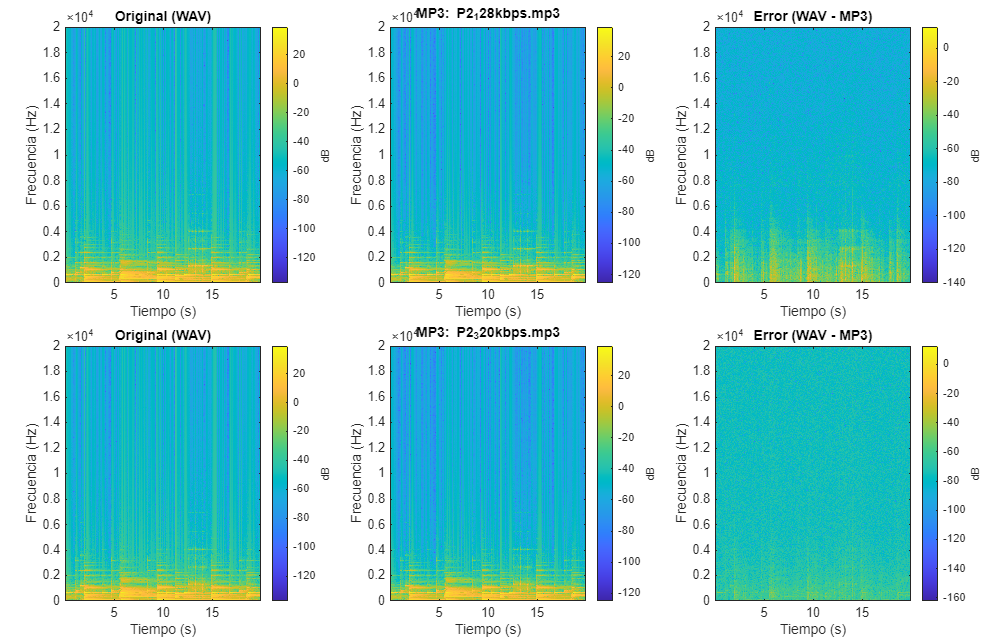


%% ---------- Visual: espectrogramas (WAV / MP3 / Error) ----------
figSP = figure('Color','w','Position',[80 80 1400 900]);
tlSP = tiledlayout(figSP, numel(pairs),3,'TileSpacing','compact','Padding','compact');
for i=1:numel(pairs)
    xr = pairs(i).x_cmp; yr = pairs(i).y_cmp; e = xr-yr;
    ax = nexttile(tlSP);  spectro_db(xr, Fs, W, hop, ax); title(ax,'Original (WAV)');
    ax = nexttile(tlSP);  spectro_db(yr, Fs, W, hop, ax); title(ax,sprintf('MP3: %s', strip_filename(pairs(i).name)));
    ax = nexttile(tlSP);  spectro_db(e,  Fs, W, hop, ax); title(ax,'Error (WAV - MP3)');
end

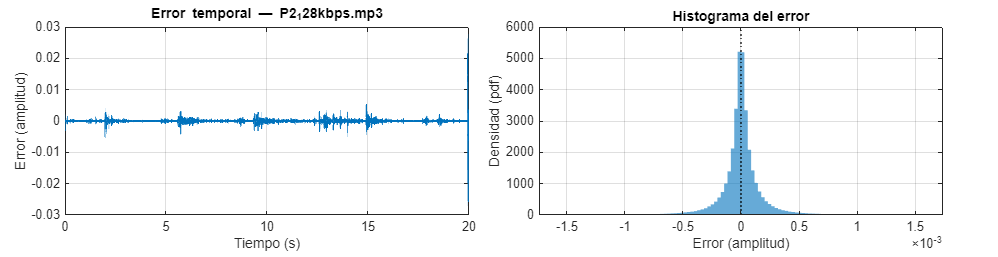


%% ---------- Visual: error temporal + histograma (primer MP3, FIX) ----------
e  = pairs(1).x_cmp - pairs(1).y_cmp;
tt = (0:numel(e)-1)/Fs;

figErr = figure('Color','w','Position',[80 1000 1400 360]);
tl = tiledlayout(figErr, 1, 2, 'TileSpacing','compact','Padding','compact');

ax1 = nexttile(tl);
plot(ax1, tt, e, 'LineWidth', 1.0);
grid(ax1,'on'); box(ax1,'on');
xlabel(ax1,'Tiempo (s)'); ylabel(ax1,'Error (amplitud)');
title(ax1, sprintf('Error temporal — %s', strip_filename(pairs(1).name)));

ax2 = nexttile(tl);
set(ax2,'XScale','linear','YScale','linear');   % evita heredar escala log
L = prctile(abs(e), 99.5);                       % rango robusto
if L <= 0, L = 3*std(e); end
if L <= 0, L = max(1e-6, max(abs(e))); end
edges = linspace(-L, L, 121);                    % 120 bins
histogram(ax2, e, 'BinEdges', edges, 'Normalization','pdf', 'EdgeColor','none');
grid(ax2,'on'); box(ax2,'on'); xlim(ax2, [-L L]);
xlabel(ax2,'Error (amplitud)'); ylabel(ax2,'Densidad (pdf)');
title(ax2,'Histograma del error'); hold(ax2,'on');
yl = ylim(ax2); plot(ax2, [0 0], yl, 'k:', 'LineWidth', 1); hold(ax2,'off');

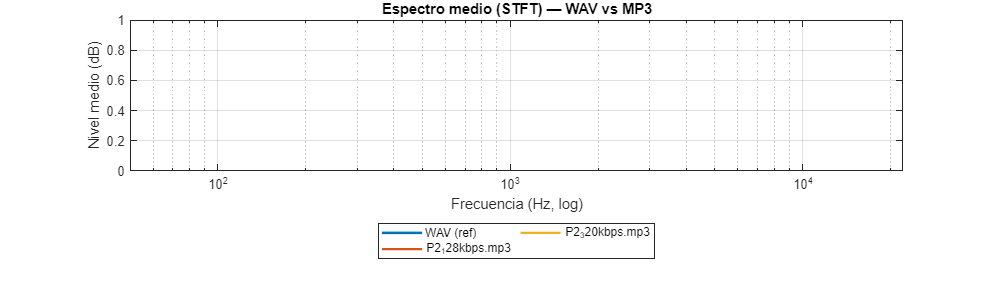


%% ---------- Visual: comparación espectral promedio (STFT, con ejes propios) ----------
figSpec = figure('Color','w','Position',[80 1380 1400 420]);
axS = axes(figSpec); hold(axS,'on'); grid(axS,'on'); box(axS,'on');
[fX, SX] = avg_mag_spectrum(pairs(1).x_cmp, Fs, W, hop);
plot(axS, fX, 20*log10(SX+eps), 'LineWidth',1.8, 'DisplayName','WAV (ref)');
for i=1:numel(pairs)
    [fY, SY] = avg_mag_spectrum(pairs(i).y_cmp, Fs, W, hop);
    plot(axS, fY, 20*log10(SY+eps), 'LineWidth',1.6, 'DisplayName', strip_filename(pairs(i).name));
end
set(axS,'XScale','log'); xlim(axS,[50 Fs/2]);
xlabel(axS,'Frecuencia (Hz, log)'); ylabel(axS,'Nivel medio (dB)');
title(axS,'Espectro medio (STFT) — WAV vs MP3');
legend(axS,'Location','southoutside','NumColumns',max(2,numel(pairs)));


%% ---------- Comparaciones auditivas ----------
fprintf('\n[Escucha A/B] Reproduciendo WAV (referencia)...\n');


[Escucha A/B] Reproduciendo WAV (referencia)...


soundsc(pairs(1).x_cmp, Fs); pause(numel(pairs(1).x_cmp)/Fs + 0.6);
for i = 1:numel(pairs)
    fprintf('Reproduciendo MP3 #%d: %s\n', i, strip_filename(pairs(i).name));
    soundsc(pairs(i).y_cmp, Fs); pause(numel(pairs(i).y_cmp)/Fs + 0.6);
end

Reproduciendo MP3 #1: P2_128kbps.mp3
Reproduciendo MP3 #2: P2_320kbps.mp3



errGain_dB = 12; errGain = 10^(errGain_dB/20);
for i = 1:numel(pairs)
    e = pairs(i).x_cmp - pairs(i).y_cmp;
    eAud = errGain * e / (max(abs(e))+eps);
    fprintf('[Error audible] %s (ganancia %+ddB)\n', strip_filename(pairs(i).name), errGain_dB);
    soundsc(eAud, Fs); pause(numel(eAud)/Fs + 0.6);
end

[Error audible] P2_128kbps.mp3 (ganancia +12dB)
[Error audible] P2_320kbps.mp3 (ganancia +12dB)



if numel(pairs) >= 2
    yABX = pairs(end).y_cmp;      % normalmente el de menor bitrate
else
    yABX = pairs(1).y_cmp;
end
fprintf('\n[ABX] Se oirán A (WAV), B (MP3) y X (A o B al azar). Intenta adivinar X.\n');


[ABX] Se oirán A (WAV), B (MP3) y X (A o B al azar). Intenta adivinar X.


soundsc(pairs(1).x_cmp, Fs); pause(numel(pairs(1).x_cmp)/Fs + 0.6);
soundsc(yABX, Fs);          pause(numel(yABX)/Fs + 0.6);
if rand > 0.5, X = pairs(1).x_cmp; lab = 'A'; else, X = yABX; lab = 'B'; end
soundsc(X, Fs); pause(numel(X)/Fs + 0.3);
input('Pulsa ENTER para revelar X...'); fprintf('X era: %s\n', lab);

X era: A



%% ---------- Export WAVs alineados y errores (para revisión externa) ----------
outAuds = fullfile(pwd,'mp3_out');
if ~exist(outAuds,'dir'), mkdir(outAuds); end
audiowrite(fullfile(outAuds,'ref_aligned.wav'), pairs(1).x_cmp, Fs);
for i = 1:numel(pairs)
    e = pairs(i).x_cmp - pairs(i).y_cmp;
    eAud = errGain * e / (max(abs(e))+eps);
    audiowrite(fullfile(outAuds, ['mp3_aligned_' num2str(i) '.wav']), pairs(i).y_cmp, Fs);
    audiowrite(fullfile(outAuds, ['error_audible_' num2str(i) '.wav']), eAud, Fs);
end

fprintf('Exportado en: %s (ref_aligned, mp3_aligned_*, error_audible_*)\n', outAuds);

Exportado en: C:\Users\andre\Desktop\Universidad\ICAI\4\Stel\Practicas\PracticasSTM\PracticasSTM\P4\Matlab MPEG1_III\mp3_out (ref_aligned, mp3_aligned_*, error_audible_*)



%% ========================= FUNCIONES LOCALES =========================
function [lag, y_al] = align_by_xcorr(x,y,Fs)
    % Alinea y -> x via correlación (ventana ±0.2 s). Devuelve lag (muestras) y y alineada.
    L = min(numel(x), numel(y));
    x = x(1:L); y = y(1:L);
    maxLag = 2*round(0.2*Fs);
    [c,lags] = xcorr(y, x, maxLag, 'coeff'); %#ok<ASGLU>
    [~,I] = max(c); lag = lags(I);
    if lag > 0
        y_al = [y(1+lag:end); zeros(lag,1)];
    elseif lag < 0
        y_al = [zeros(-lag,1); y(1:end+lag)];
    else
        y_al = y;
    end
end

function v = seg_snr(x,y,W,hop)
    % Segmental-SNR (dB) medio por tramas (cap a [-10,35] dB).
    [Sx,~] = stft_mag(x,W,hop); [Sy,~] = stft_mag(y,W,hop);
    Ex = sum(Sx.^2,1); Ee = sum((Sx-Sy).^2,1);
    snr_f = 10*log10((Ex+eps)./(Ee+eps));
    snr_f = max(-10, min(35, snr_f));
    v = mean(snr_f);
end

function d = lsd_stft(x,y,W,hop)
    % Log-Spectral Distance medio (dB) sobre STFT (RMSE en dB por trama).
    [Sx,~] = stft_mag(x,W,hop); [Sy,~] = stft_mag(y,W,hop);
    X = 20*log10(Sx + eps); Y = 20*log10(Sy + eps);
    d = mean( sqrt(mean((X - Y).^2, 1)) );
end

function [S,F] = stft_mag(x,W,hop)
    N = numel(W); nfft = 2^nextpow2(N);
    [Sx,F,~] = spectrogram(x, W, N-hop, nfft, 'onesided');
    S = abs(Sx);
end

function spectro_db(x,Fs,W,hop,ax)
    if nargin<5 || isempty(ax), ax = gca; end
    N = numel(W); nfft = 2^nextpow2(N);
    [S,F,T] = spectrogram(x, W, N-hop, nfft, Fs, 'yaxis');
    SdB = 20*log10(abs(S)+eps);
    imagesc(ax, T, F, SdB); axis(ax,'xy');
    ylim(ax, [0 min(20000, Fs/2)]);
    c = colorbar(ax); c.Label.String='dB';
    xlabel(ax,'Tiempo (s)'); ylabel(ax,'Frecuencia (Hz)');
end

function [f, Sm] = avg_mag_spectrum(x, Fs, W, hop)
    [S,F] = stft_mag(x,W,hop);
    Sm = mean(S,2); f = F;
end

function s = strip_filename(p)
    % Devuelve 'nombre.ext' como char escalar (apto para DisplayName)
    if isstring(p), p = char(p); end
    [~,n,ext] = fileparts(p);
    s = [n ext];
end

%% PARTE 2 · (e) — Comparación con MP3 exportado en Audacity
% Ficheros: WAV original y MP3 exportado en Audacity: 'P4audioSTMAudacity.mp3'

clear; clc;

% ---------- Rutas de entrada ----------
wavFile = 'P4audioSTM.wav';                       % ajusta si tu WAV se llama distinto
mp3Aud  = 'P4audioSTMAudacity.mp3';               % MP3 exportado desde Audacity
assert(isfile(wavFile), 'No se encuentra el WAV: %s', wavFile);
assert(isfile(mp3Aud),  'No se encuentra el MP3 de Audacity: %s', mp3Aud);

% ---------- Tamaños y ratio de compresión ----------
sW = dir(wavFile); sM = dir(mp3Aud);
wavMB = sW.bytes/1024/1024; mp3MB = sM.bytes/1024/1024;
ratio = sW.bytes / sM.bytes;
fprintf('--- Parte 2 (e): Tamaños y ratio ---\n');

--- Parte 2 (e): Tamaños y ratio ---


fprintf('WAV:  %s | %.2f MB\n', sW.name, wavMB);

WAV:  P4audioSTM.wav | 5.04 MB


fprintf('MP3:  %s | %.2f MB\n', sM.name, mp3MB);

MP3:  P4audioSTMAudacity.mp3 | 0.32 MB


fprintf('Ratio de compresión WAV/MP3 = %.2f : 1  (reducción %.1f%%)\n\n', ratio, 100*(1-mp3MB/wavMB));

Ratio de compresión WAV/MP3 = 15.89 : 1  (reducción 93.7%)




% ---------- Lectura, mono y remuestreo si procede ----------
[x,Fs] = audioread(wavFile); if size(x,2)>1, x = mean(x,2); end
[y,FsY] = audioread(mp3Aud); if size(y,2)>1, y = mean(y,2); end
if FsY~=Fs, y = resample(y, Fs, FsY); end
x = x(:); y = y(:);

% ---------- Alineación (compensa retardo/padding) + igualación de nivel ----------
[lag, y_al] = align_by_xcorr(x, y, Fs);
N   = min(numel(x), numel(y_al));
xr  = x(1:N);
yr  = y_al(1:N);
gain = rms(xr)/max(rms(yr),eps);
yr  = yr * gain;
e   = xr - yr;

fprintf('Alineación: lag = %d muestras (%.3f ms) | ganancia aplicada = %.3f\n\n', ...
        lag, 1000*lag/Fs, gain);

Alineación: lag = 577 muestras (13.084 ms) | ganancia aplicada = 1.000




% ---------- Métricas objetivas ----------
W = hamming(2048,'periodic'); hop = 512;
SNR     = 20*log10(rms(xr)/max(rms(e),eps));
SegSNR  = seg_snr(xr, yr, W, hop);
RMSE    = sqrt(mean(e.^2));
LSD     = lsd_stft(xr, yr, W, hop);

fprintf('--- Métricas WAV vs MP3 (Audacity) ---\n');

--- Métricas WAV vs MP3 (Audacity) ---


fprintf('SNR       = %.2f dB\n', SNR);

SNR       = 42.51 dB


fprintf('SegSNR    = %.2f dB\n', SegSNR);

SegSNR    = 34.99 dB


fprintf('RMSE      = %.5f\n', RMSE);

RMSE      = 0.00037


fprintf('LSD(STFT) = %.2f dB\n\n', LSD);

LSD(STFT) = 2.01 dB



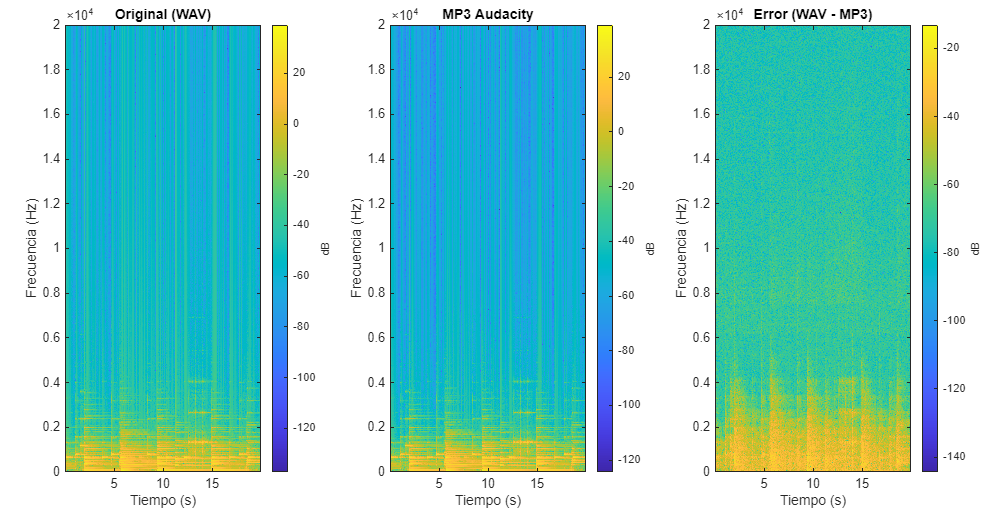


% ---------- Gráficas: espectrogramas (WAV / MP3 / Error) ----------
figure('Color','w','Position',[80 80 1400 720]);
tl = tiledlayout(1,3,'TileSpacing','compact','Padding','compact');
ax = nexttile;  spectro_db(xr, Fs, W, hop, ax);  title(ax,'Original (WAV)');
ax = nexttile;  spectro_db(yr, Fs, W, hop, ax);  title(ax,'MP3 Audacity');
ax = nexttile;  spectro_db(e,  Fs, W, hop, ax);  title(ax,'Error (WAV - MP3)');

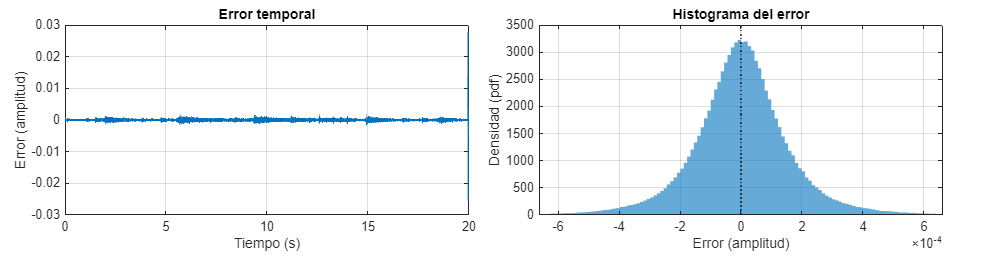


% ---------- Gráficas: error temporal + histograma ----------
tt = (0:numel(e)-1)/Fs;
figErr = figure('Color','w','Position',[80 860 1400 360]);
tl2 = tiledlayout(figErr, 1, 2, 'TileSpacing','compact','Padding','compact');

ax1 = nexttile(tl2);
plot(ax1, tt, e, 'LineWidth', 1.0); grid(ax1,'on'); box(ax1,'on');
xlabel(ax1,'Tiempo (s)'); ylabel(ax1,'Error (amplitud)');
title(ax1,'Error temporal');

ax2 = nexttile(tl2);
set(ax2,'XScale','linear','YScale','linear');
L = prctile(abs(e), 99.5); if L<=0, L = max(3*std(e), 1e-6); end
edges = linspace(-L, L, 121);
histogram(ax2, e, 'BinEdges', edges, 'Normalization','pdf', 'EdgeColor','none');
grid(ax2,'on'); box(ax2,'on'); xlim(ax2, [-L L]);
xlabel(ax2,'Error (amplitud)'); ylabel(ax2,'Densidad (pdf)');
title(ax2,'Histograma del error'); hold(ax2,'on');
yl = ylim(ax2); plot(ax2,[0 0], yl, 'k:', 'LineWidth',1); hold(ax2,'off');

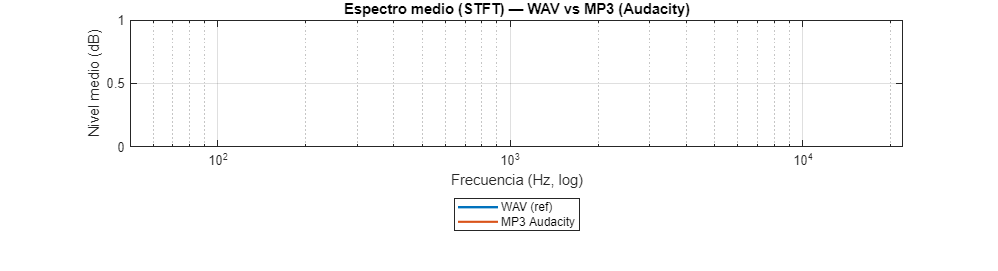


% ---------- Gráfica: espectro medio (STFT) ----------
figure('Color','w','Position',[80 1240 1400 380]);
axS = axes; hold(axS,'on'); grid(axS,'on'); box(axS,'on');
[fX, SX] = avg_mag_spectrum(xr, Fs, W, hop);
[fY, SY] = avg_mag_spectrum(yr, Fs, W, hop);
plot(axS, fX, 20*log10(SX+eps), 'LineWidth',1.8, 'DisplayName','WAV (ref)');
plot(axS, fY, 20*log10(SY+eps), 'LineWidth',1.6, 'DisplayName','MP3 Audacity');
set(axS,'XScale','log'); xlim(axS,[50 Fs/2]);
xlabel(axS,'Frecuencia (Hz, log)'); ylabel(axS,'Nivel medio (dB)');
title(axS,'Espectro medio (STFT) — WAV vs MP3 (Audacity)');
legend(axS,'Location','southoutside');


% ---------- Comparación auditiva (opcional) ----------
% soundsc(xr, Fs); pause(numel(xr)/Fs + 0.5);       % WAV
% soundsc(yr, Fs); pause(numel(yr)/Fs + 0.5);       % MP3 Audacity
% errGain_dB = 12; eAud = 10^(errGain_dB/20) * e / (max(abs(e))+eps);
% soundsc(eAud, Fs);                                 % "error audible"

% ---------- Export WAVs alineados y error (opcional) ----------
outDir = fullfile(pwd,'audacity_cmp'); if ~exist(outDir,'dir'), mkdir(outDir); end
audiowrite(fullfile(outDir,'ref_aligned.wav'), xr, Fs);
audiowrite(fullfile(outDir,'mp3Audacity_aligned.wav'), yr, Fs);
audiowrite(fullfile(outDir,'error_audacity.wav'), e, Fs);
fprintf('Exportado en: %s (ref_aligned.wav, mp3Audacity_aligned.wav, error_audacity.wav)\n', outDir);

Exportado en: C:\Users\andre\Desktop\Universidad\ICAI\4\Stel\Practicas\PracticasSTM\PracticasSTM\P4\Matlab MPEG1_III\audacity_cmp (ref_aligned.wav, mp3Audacity_aligned.wav, error_audacity.wav)


%% PARTE 2 (f) — Comparativa final: MATLAB/FFmpeg vs Audacity (autocontenido y robusto)
% - Busca MP3s generados (./mp3_out) y el MP3 de Audacity (P4audioSTMAudacity.mp3)
% - Alinea con el WAV original, iguala niveles y calcula métricas: SNR, SegSNR, RMSE, LSD
% - Compara tamaños y ratios de compresión
% - Genera tabla, CSV y figuras resumen (SNR y LSD)

clear; clc;

%% -------- Entradas --------
wavFile     = 'P4audioSTM.wav';           % WAV original
audacityMp3 = 'P4audioSTMAudacity.mp3';   % MP3 exportado desde Audacity
mp3Dir      = fullfile(pwd,'mp3_out');    % MP3s generados en (a)-(d), si existen

assert(isfile(wavFile), 'No se encuentra el WAV: %s', wavFile);
hasAud = isfile(audacityMp3);

%% -------- Localiza MP3s a comparar (cell array robusto) --------
mp3List = {};   % vector columna de celdas (rutas completas)
if isfolder(mp3Dir)
    d = dir(fullfile(mp3Dir,'*.mp3'));
    if ~isempty(d)
        mp3List = [mp3List; fullfile({d.folder},{d.name}).'];  % cell col
    end
end
if hasAud
    mp3List = [mp3List; {audacityMp3}];
end
% Elimina duplicados manteniendo orden
[~, ia] = unique(mp3List, 'stable');
mp3List = mp3List(sort(ia));
assert(~isempty(mp3List), 'No se ha encontrado ningún MP3 para comparar.');

%% -------- Lectura WAV (mono) --------
[x,Fs] = audioread(wavFile);
if size(x,2)>1, x = mean(x,2); end
x = x(:);

%% -------- Métricas por cada MP3 (alineación + SNR/SegSNR/RMSE/LSD) --------
W = hamming(2048,'periodic'); hop = 512;

N = numel(mp3List);
NAMES    = strings(N,1);
SNRs     = nan(N,1);
SegSNRs  = nan(N,1);
RMSEs    = nan(N,1);
LSDs     = nan(N,1);
LAGS     = nan(N,1);
SIZES_MB = nan(N,1);
RATIOS   = nan(N,1);

sW   = dir(wavFile);
wavB = sW.bytes; wavMB = wavB/1024/1024;

for i = 1:N
    f = mp3List{i};                       % OJO: char desde cell
    [y,FsY] = audioread(f);
    if size(y,2)>1, y = mean(y,2); end
    if FsY~=Fs, y = resample(y, Fs, FsY); end
    y = y(:);

    % Alinear y -> x e igualar nivel RMS
    [lag, y_al] = align_by_xcorr(x, y, Fs);
    L = min(numel(x), numel(y_al));
    xr = x(1:L);
    yr = y_al(1:L);
    g  = rms(xr)/max(rms(yr),eps);
    yr = yr * g;
    e  = xr - yr;

    % Métricas
    SNRs(i)     = 20*log10(rms(xr)/max(rms(e),eps));
    SegSNRs(i)  = seg_snr(xr, yr, W, hop);
    RMSEs(i)    = sqrt(mean(e.^2));
    LSDs(i)     = lsd_stft(xr, yr, W, hop);
    LAGS(i)     = lag;

    % Tamaños/ratio
    si          = dir(f);
    SIZES_MB(i) = si.bytes/1024/1024;
    RATIOS(i)   = wavB / max(si.bytes,1);

    % Nombre legible
    NAMES(i)    = label_file(f);
end

%% -------- Tabla comparativa + CSV --------
metricsAll = table( ...
    NAMES, SNRs, SegSNRs, RMSEs, LSDs, LAGS, SIZES_MB, RATIOS, ...
    'VariableNames', {'Archivo','SNR_dB','SegSNR_dB','RMSE','LSD_dB','Lag_muestras','Tamano_MB','Ratio_WAV_div'});

disp('--- Parte 2 (f): Comparativa de métricas ---');

--- Parte 2 (f): Comparativa de métricas ---


disp(metricsAll);

        Archivo         SNR_dB    SegSNR_dB       RMSE       LSD_dB    Lag_muestras    Tamano_MB    Ratio_WAV_div
    ________________    ______    _________    __________    ______    ____________    _________    _____________

    "P2_128kbps.mp3"    38.596     34.953      0.00057469    2.0745        1729         0.30576        16.477    
    "P2_320kbps.mp3"    39.571     34.961      0.00051369    1.5754        1729         0.76435        6.5914    
    "Audacity MP3"       42.51     34.995       0.0003662    2.0067         577         0.31711        15.888    




writetable(metricsAll, 'P42f_metricas_comparativa.csv');
fprintf('CSV guardado: P42f_metricas_comparativa.csv (WAV=%.2f MB)\n', wavMB);

CSV guardado: P42f_metricas_comparativa.csv (WAV=5.04 MB)


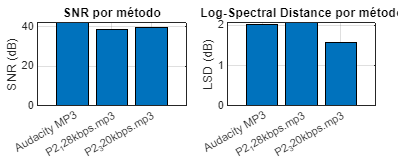


%% -------- Figuras resumen (SNR y LSD) --------
figure('Color','w','Position',[100 100 1000 420]);
tiledlayout(1,2,'TileSpacing','compact','Padding','compact');

nexttile;
bar(categorical(metricsAll.Archivo), metricsAll.SNR_dB);
grid on; ylabel('SNR (dB)'); title('SNR por método');

nexttile;
bar(categorical(metricsAll.Archivo), metricsAll.LSD_dB);
grid on; ylabel('LSD (dB)'); title('Log-Spectral Distance por método');


function s = label_file(p)
    % Devuelve un nombre legible para tabla/leyenda
    if isstring(p), p = char(p); end
    [~,n,ext] = fileparts(p);
    s = string([n ext]);
    if contains(lower(s), 'audacity')
        s = "Audacity MP3";
    end
end
